## Ejercicio Dos

Toma las imágenes propuestas que est ́an en escala de grises. Represen- ta cada una de ellas en pseudocolor utilizando el m ́etodo de rebanado de intensidad. Haz que tu funci ́on pueda recibir como parametro la imagen y el número de niveles de color a representar. Prohibido utilizar las funciones de matlab: pcolor, imagesc, colormap, image. 						

originalImage = rgb2gray(imread("Imagenes/cadera_1.jpg"));
num_niveles = [5,10,15,20,35];

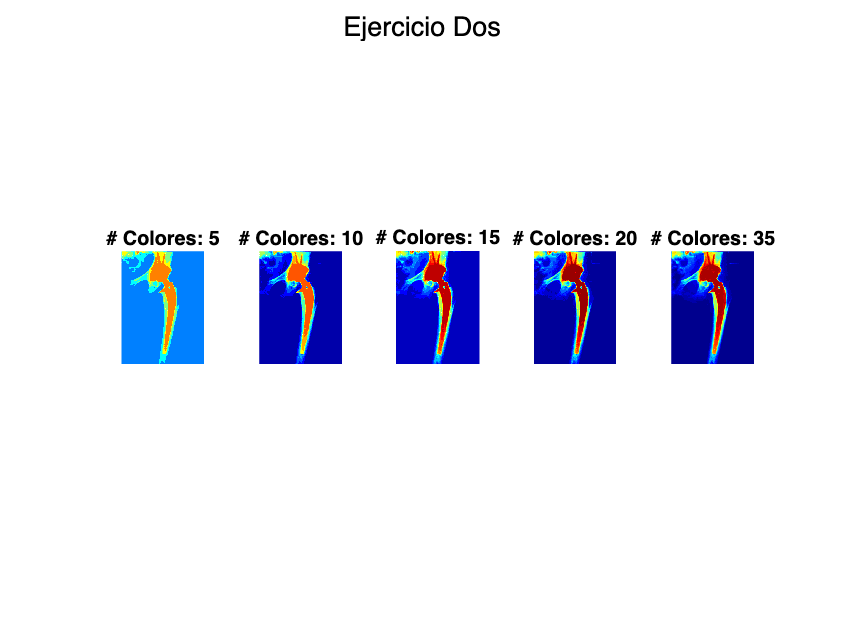

results01 = cell(1, length(num_niveles));
for i = 1:length(num_niveles)
    results01{i} = pseudocolor(originalImage, num_niveles(i));
end
showMultipleImages('Ejercicio Dos',results01,num_niveles);

function resultImage = pseudocolor(imagen, num_niveles)

    minIntensity = double(min(imagen(:))); % El valor más chico en la intensidad en escala de grises
    maxIntensity = double(max(imagen(:))); % El valor más grande en la intensidad en escala de grises
    
    % Calcular los niveles de intensidad para rebanar
    niveles_intensidad = linspace(minIntensity, maxIntensity, num_niveles + 1);

    % Crear una matriz para la imagen en pseudocolor
    [filas, columnas] = size(imagen);
    resultImage = zeros(filas, columnas, 3);

    % Definir colores para cada intervalo de intensidad
    colores = jet(num_niveles);

    % Para cada intervalo de intensidad
    for i = 1:num_niveles
        % Máscara booleana para los píxeles en el intervalo
        mascara = (imagen >= niveles_intensidad(i)) & (imagen <= niveles_intensidad(i+1));

        % Asignar color al
        resultImage(:,:,1) = resultImage(:,:,1) + mascara * colores(i, 1);
        resultImage(:,:,2) = resultImage(:,:,2) + mascara * colores(i, 2);
        resultImage(:,:,3) = resultImage(:,:,3) + mascara * colores(i, 3);
    end
end

#### showMultipleImages

Dada una celda de imágenes y un conjunto de etiquetas, estas se presentan en una nueva ventana. 

function showMultipleImages(figure_title, images, image_labels)
    m = length(images);
    figure;
    for i = 1:m
        subplot(1, m, i);
        imshow(images{i},[]);
        title(['# Colores: ', num2str(image_labels(i))]);
    end
    sgtitle(figure_title); 
end